syms E I L M I B EA
L=0.1;                   %%m
E=850*1000;             %%pa
mu0=4*pi*10^-7;
Br=0.4;                    %T
M=Br/mu0         %%A/m

M = 3.1831e+05

D=0.002;
D2=0.001;
A=D^2*pi/4;
I=D^4*pi/64-D2^4*pi/64;
 ;                %%A/m 
v1=0.002*pi*D^2/4;      %%h=2mm
v11=0.006*pi*D^2/16;        %%h=4mm
v2=0.002*pi*D^2/4;
dl = L/10000 ;        %% 분해능
EN=2;
figure
hold on
xlim([-2,14])
ylim([-8,8])
MarkerSize = 1

MarkerSize = 1

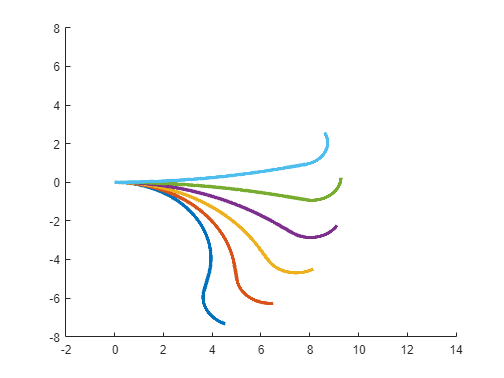


국소 최솟값이 있을 수 있습니다. 제약 조건이 충족되었습니다.

현재 스텝의 크기가 스텝 크기 허용오차 값보다 작고 
제약 조건이 제약 조건 허용오차의 값 이내에서 
충족되기 때문에 fmincon이(가) 중지되었습니다.

<중지 기준 세부 정보>


ans =  -103.0293  -23.3482



국소 최솟값이 있을 수 있습니다. 제약 조건이 충족되었습니다.

현재 스텝의 크기가 스텝 크기 허용오차 값보다 작고 
제약 조건이 제약 조건 허용오차의 값 이내에서 
충족되기 때문에 fmincon이(가) 중지되었습니다.

<중지 기준 세부 정보>


ans =   -82.0901    3.6607



국소 최솟값이 있을 수 있습니다. 제약 조건이 충족되었습니다.

현재 스텝의 크기가 스텝 크기 허용오차 값보다 작고 
제약 조건이 제약 조건 허용오차의 값 이내에서 
충족되기 때문에 fmincon이(가) 중지되었습니다.

<중지 기준 세부 정보>


ans =   -59.3664   31.8410



국소 최솟값이 있을 수 있습니다. 제약 조건이 충족되었습니다.

현재 스텝의 크기가 스텝 크기 허용오차 값보다 작고 
제약 조건이 제약 조건 허용오차의 값 이내에서 
충족되기 때문에 fmincon이(가) 중지되었습니다.

<중지 기준 세부 정보>


ans =   -35.9330   60.1788



국소 최솟값이 있을 수 있습니다. 제약 조건이 충족되었습니다.

현재 스텝의 크기가 스텝 크기 허용오차 값보다 작고 
제약 조건이 제약 조건 허용오차의 값 이내에서 
충족되기 때문에 fmincon이(가) 중지되었습니다.

<중지 기준 세부 정보>


ans =   -11.9990   88.6247



제약 조건을 충족하는 국소 최솟값을 찾았습니다.

목적 함수가 최적성 허용오차의 값 이내에서 실현 가능한 방향에서 감소하지 않고 
제약 조건이 제약 조건 허용오차의 값 이내에서 충족되기 때문에 
최적화가 완료되었습니다.

<중지 기준 세부 정보>


ans =    12.3051  117.1479



H=40000;
L1=0.075;

ML=0.008;
L=L-ML;
L1=L1-0.5*ML;
for  thetaB2=[1 30 60 90 120 150];
        
            fun = @(x) x(1)^2+x(2)^2;
            A = [];
            b = [];
            Aeq = [];
            beq = [];
            lb = [];
            ub = [];
            c = @(x) abs(abs(x(1))-abs(x(2)))-pi;
                

            EA0=[0 0];
            ceq=@(x) [EN*E*I*x(1)/-((H*M*v11*mu0*sin((thetaB2*pi/180)-x(1)))-(H*M*v2*mu0*sin((thetaB2*pi/180)-x(2))))-L1;...
            (E*I*(x(2)-x(1))/(H*M*v2*mu0*sin((thetaB2*pi/180)-x(2))))-L+L1];
            nonlinfcn = @(x)deal(c(x),ceq(x));
            x = fmincon(fun,EA0,A,b,Aeq,beq,lb,ub,nonlinfcn);
            A1lin=linspace(0,x(1),500);
            A2lin=linspace(x(1),x(2),500);
            x1=EN*E*I*sin(A1lin)/(-(H*M*v11*mu0*sin((thetaB2*pi/180)-x(1)))+(H*M*v2*mu0*sin((thetaB2*pi/180)-x(2))));
        y1=EN*E*I*(1-cos(A1lin))/(-(H*M*v11*mu0*sin((thetaB2*pi/180)-x(1)))+(H*M*v2*mu0*sin((thetaB2*pi/180)-x(2))));
    
        x10=EN*E*I*sin(x(1))/(-(H*M*v11*mu0*sin((thetaB2*pi/180)-x(1)))+(H*M*v2*mu0*sin((thetaB2*pi/180)-x(2))));
        y10=EN*E*I*(1-cos(x(1)))/(-(H*M*v11*mu0*sin((thetaB2*pi/180)-x(1)))+(H*M*v2*mu0*sin((thetaB2*pi/180)-x(2))));
    x20=ML*cos(x(1));
    y20=ML*sin(x(1));

        x2=(E*I*(sin(A2lin)-sin(x(1)))/(H*M*v2*mu0*sin((thetaB2*pi/180)-x(2))))+x10+x20;
        y2=(E*I*(cos(x(1))-cos(A2lin))/(H*M*v2*mu0*sin((thetaB2*pi/180)-x(2))))+y10+y20;
    
    
        xtotal=[x1,x2];
        ytotal=[y1,y2];
        plot(100*xtotal,100*ytotal,'LineWidth',3)
        
        x*180/pi


      

end      

   
       
%n0y=linspace(0,0,1000);
       % n0x=linspace(0,0.1,1000);
      %  plot(n0x,n0y,'LineWidth',3)


   

    
             syms E I L M I B EA
L=0.1;                   %%m
E=750*1000;             %%pa
mu0=4*pi*10^-7;
Br=1.0;                    %T
M=Br/mu0         %%A/m

M = 7.9577e+05

D=0.002;
D2=0.001;
A=D^2*pi/4;
I=D^4*pi/64-D2^4*pi/64;
 ;                %%A/m 
v1=0.002*pi*D^2/4;      %%h=2mm
v11=0.004*pi*D^2/16;        %%h=4mm
v2=0.002*pi*D^2/4;
dl = L/10000 ;        %% 분해능



syms A A10 A20 Alpha

figure
hold on
xlim([-L,L])
ylim([-180,180])
%xlim([-0.5*L,1.5*L])
%ylim([-L,L])
MarkerSize = 1

MarkerSize = 1


H=30000;


L1=0.01

L1 = 0.0100

    for  thetaB2= 10:10:160
            fun = @(x) x(1)^2+x(2)^2;
            A = [];
            b = [];
            Aeq = [];
            beq = [];
            lb = [];
            ub = [];
            c = @(x) abs(abs(x(1))-abs(x(2)))-pi;
            EA0=[0 0];
            ceq=@(x) [E*I*x(1)/-((H*M*v11*mu0*sin((thetaB2*pi/180)-x(1)))-(H*M*v2*mu0*sin((thetaB2*pi/180)-x(2))))-L1;...
            (E*I*(x(2)-x(1))/(H*M*v2*mu0*sin((thetaB2*pi/180)-x(2))))-L+L1];
            nonlinfcn = @(x)deal(c(x),ceq(x));
            x = fmincon(fun,EA0,A,b,Aeq,beq,lb,ub,nonlinfcn);
            A1lin=linspace(0,x(1),500);
            A2lin=linspace(x(1),x(2),500);
            x1=E*I*sin(A1lin)/(-(H*M*v11*mu0*sin((thetaB2*pi/180)-x(1)))+(H*M*v2*mu0*sin((thetaB2*pi/180)-x(2))));
        y1=E*I*(1-cos(A1lin))/(-(H*M*v11*mu0*sin((thetaB2*pi/180)-x(1)))+(H*M*v2*mu0*sin((thetaB2*pi/180)-x(2))));
    
        x10=E*I*sin(x(1))/(-(H*M*v11*mu0*sin((thetaB2*pi/180)-x(1)))+(H*M*v2*mu0*sin((thetaB2*pi/180)-x(2))));
        y10=E*I*(1-cos(x(1)))/(-(H*M*v11*mu0*sin((thetaB2*pi/180)-x(1)))+(H*M*v2*mu0*sin((thetaB2*pi/180)-x(2))));
    
        x2=(E*I*(sin(A2lin)-sin(x(1)))/(H*M*v2*mu0*sin((thetaB2*pi/180)-x(2))))+x10;
        y2=(E*I*(cos(x(1))-cos(A2lin))/(H*M*v2*mu0*sin((thetaB2*pi/180)-x(2))))+y10;
    
    
        xtotal=[x1,x2];
        ytotal=[y1,y2];
        %plot(xtotal,-ytotal)
        %plot(xtotal,ytotal)
        x*180/pi;


         r=(E*I*(cos(x(1))-cos(x(2)))/(H*M*v2*mu0*sin((thetaB2*pi/180)-x(2))))+y10+(0.01*sin(x(1)));
         if r<0
            x(2)=-x(2);
            r=-r;
        end
            plot(r,x(2)*180/pi,'bo','MarkerSize',3)
            plot(-r,-x(2)*180/pi,'bo','MarkerSize',3)
   
    end      


국소 최솟값이 있을 수 있습니다. 제약 조건이 충족되었습니다.

현재 스텝의 크기가 스텝 크기 허용오차 값보다 작고 
제약 조건이 제약 조건 허용오차의 값 이내에서 
충족되기 때문에 fmincon이(가) 중지되었습니다.

<중지 기준 세부 정보>

제약 조건을 충족하는 국소 최솟값을 찾았습니다.

목적 함수가 최적성 허용오차의 값 이내에서 실현 가능한 방향에서 감소하지 않고 
제약 조건이 <a href = "matlab

    L1=0.02

L1 = 0.0200

    for  thetaB2= 10:10:160
            fun = @(x) x(1)^2+x(2)^2;
            A = [];
            b = [];
            Aeq = [];
            beq = [];
            lb = [];
            ub = [];
            c = @(x) abs(abs(x(1))-abs(x(2)))-pi;
            EA0=[0 0];
            ceq=@(x) [E*I*x(1)/-((H*M*v11*mu0*sin((thetaB2*pi/180)-x(1)))-(H*M*v2*mu0*sin((thetaB2*pi/180)-x(2))))-L1;...
            (E*I*(x(2)-x(1))/(H*M*v2*mu0*sin((thetaB2*pi/180)-x(2))))-L+L1];
            nonlinfcn = @(x)deal(c(x),ceq(x));
            x = fmincon(fun,EA0,A,b,Aeq,beq,lb,ub,nonlinfcn);
            A1lin=linspace(0,x(1),500);
            A2lin=linspace(x(1),x(2),500);
            x1=E*I*sin(A1lin)/(-(H*M*v11*mu0*sin((thetaB2*pi/180)-x(1)))+(H*M*v2*mu0*sin((thetaB2*pi/180)-x(2))));
        y1=E*I*(1-cos(A1lin))/(-(H*M*v11*mu0*sin((thetaB2*pi/180)-x(1)))+(H*M*v2*mu0*sin((thetaB2*pi/180)-x(2))));
    
        x10=E*I*sin(x(1))/(-(H*M*v11*mu0*sin((thetaB2*pi/180)-x(1)))+(H*M*v2*mu0*sin((thetaB2*pi/180)-x(2))));
        y10=E*I*(1-cos(x(1)))/(-(H*M*v11*mu0*sin((thetaB2*pi/180)-x(1)))+(H*M*v2*mu0*sin((thetaB2*pi/180)-x(2))));
    
        x2=(E*I*(sin(A2lin)-sin(x(1)))/(H*M*v2*mu0*sin((thetaB2*pi/180)-x(2))))+x10;
        y2=(E*I*(cos(x(1))-cos(A2lin))/(H*M*v2*mu0*sin((thetaB2*pi/180)-x(2))))+y10;
    
    
        xtotal=[x1,x2];
        ytotal=[y1,y2];
        %plot(xtotal,-ytotal)
        %plot(xtotal,ytotal)
        x*180/pi;


         r=(E*I*(cos(x(1))-cos(x(2)))/(H*M*v2*mu0*sin((thetaB2*pi/180)-x(2))))+y10+(0.01*sin(x(1)));
         if r<0
            x(2)=-x(2);
            r=-r;
        end
            plot(r,x(2)*180/pi,'ro','MarkerSize',3)
            plot(-r,-x(2)*180/pi,'ro','MarkerSize',3)
   
    end      


실현불가능점으로 수렴되었습니다.

제약 조건 허용오차 값 내에서 제약 조건을 충족하는 점을
국소적으로 찾을 수 없기 때문에 fmincon이(가) 중지되었습니다.

<중지 기준 세부 정보>

내점법 실현가능성 모드를 활성화해 보십시오.


제약 조건을 충족하는 국소 최솟값을 찾았습니다.

목적 함수가 최적성 허용오차의 값 이내에서 실현 가능한 방향에서 감소하지 않고 
제약 조건이 제약 조건 허용오차의 값 이내에서 충족되기 때문에 
최적화가 완료되었습니다.

<<a href = "matla

      L1=0.03

L1 = 0.0300

    for  thetaB2= 10:10:160
            fun = @(x) x(1)^2+x(2)^2;
            A = [];
            b = [];
            Aeq = [];
            beq = [];
            lb = [];
            ub = [];
            c = @(x) abs(abs(x(1))-abs(x(2)))-pi;
            EA0=[0 0];
            ceq=@(x) [E*I*x(1)/-((H*M*v11*mu0*sin((thetaB2*pi/180)-x(1)))-(H*M*v2*mu0*sin((thetaB2*pi/180)-x(2))))-L1;...
            (E*I*(x(2)-x(1))/(H*M*v2*mu0*sin((thetaB2*pi/180)-x(2))))-L+L1];
            nonlinfcn = @(x)deal(c(x),ceq(x));
            x = fmincon(fun,EA0,A,b,Aeq,beq,lb,ub,nonlinfcn);
            A1lin=linspace(0,x(1),500);
            A2lin=linspace(x(1),x(2),500);
            x1=E*I*sin(A1lin)/(-(H*M*v11*mu0*sin((thetaB2*pi/180)-x(1)))+(H*M*v2*mu0*sin((thetaB2*pi/180)-x(2))));
        y1=E*I*(1-cos(A1lin))/(-(H*M*v11*mu0*sin((thetaB2*pi/180)-x(1)))+(H*M*v2*mu0*sin((thetaB2*pi/180)-x(2))));
    
        x10=E*I*sin(x(1))/(-(H*M*v11*mu0*sin((thetaB2*pi/180)-x(1)))+(H*M*v2*mu0*sin((thetaB2*pi/180)-x(2))));
        y10=E*I*(1-cos(x(1)))/(-(H*M*v11*mu0*sin((thetaB2*pi/180)-x(1)))+(H*M*v2*mu0*sin((thetaB2*pi/180)-x(2))));
    
        x2=(E*I*(sin(A2lin)-sin(x(1)))/(H*M*v2*mu0*sin((thetaB2*pi/180)-x(2))))+x10;
        y2=(E*I*(cos(x(1))-cos(A2lin))/(H*M*v2*mu0*sin((thetaB2*pi/180)-x(2))))+y10;
    
    
        xtotal=[x1,x2];
        ytotal=[y1,y2];
        %plot(xtotal,-ytotal)
        %plot(xtotal,ytotal)
        x*180/pi;


         r=(E*I*(cos(x(1))-cos(x(2)))/(H*M*v2*mu0*sin((thetaB2*pi/180)-x(2))))+y10+(0.01*sin(x(1)));
         if r<0
            x(2)=-x(2);
            r=-r;
        end
            plot(r,x(2)*180/pi,'go','MarkerSize',3)
            plot(-r,-x(2)*180/pi,'go','MarkerSize',3)
   
    end     


국소 최솟값이 있을 수 있습니다. 제약 조건이 충족되었습니다.

현재 스텝의 크기가 스텝 크기 허용오차 값보다 작고 
제약 조건이 제약 조건 허용오차의 값 이내에서 
충족되기 때문에 fmincon이(가) 중지되었습니다.

<중지 기준 세부 정보>

제약 조건을 충족하는 국소 최솟값을 찾았습니다.

목적 함수가 최적성 허용오차의 값 이내에서 실현 가능한 방향에서 감소하지 않고 
제약 조건이 <a href = "matlab

   L1=0.04

L1 = 0.0400

    for  thetaB2= 10:10:160
            fun = @(x) x(1)^2+x(2)^2;
            A = [];
            b = [];
            Aeq = [];
            beq = [];
            lb = [];
            ub = [];
            c = @(x) abs(abs(x(1))-abs(x(2)))-pi;
            EA0=[0 0];
            ceq=@(x) [E*I*x(1)/-((H*M*v11*mu0*sin((thetaB2*pi/180)-x(1)))-(H*M*v2*mu0*sin((thetaB2*pi/180)-x(2))))-L1;...
            (E*I*(x(2)-x(1))/(H*M*v2*mu0*sin((thetaB2*pi/180)-x(2))))-L+L1];
            nonlinfcn = @(x)deal(c(x),ceq(x));
            x = fmincon(fun,EA0,A,b,Aeq,beq,lb,ub,nonlinfcn);
            A1lin=linspace(0,x(1),500);
            A2lin=linspace(x(1),x(2),500);
            x1=E*I*sin(A1lin)/(-(H*M*v11*mu0*sin((thetaB2*pi/180)-x(1)))+(H*M*v2*mu0*sin((thetaB2*pi/180)-x(2))));
        y1=E*I*(1-cos(A1lin))/(-(H*M*v11*mu0*sin((thetaB2*pi/180)-x(1)))+(H*M*v2*mu0*sin((thetaB2*pi/180)-x(2))));
    
        x10=E*I*sin(x(1))/(-(H*M*v11*mu0*sin((thetaB2*pi/180)-x(1)))+(H*M*v2*mu0*sin((thetaB2*pi/180)-x(2))));
        y10=E*I*(1-cos(x(1)))/(-(H*M*v11*mu0*sin((thetaB2*pi/180)-x(1)))+(H*M*v2*mu0*sin((thetaB2*pi/180)-x(2))));
    
        x2=(E*I*(sin(A2lin)-sin(x(1)))/(H*M*v2*mu0*sin((thetaB2*pi/180)-x(2))))+x10;
        y2=(E*I*(cos(x(1))-cos(A2lin))/(H*M*v2*mu0*sin((thetaB2*pi/180)-x(2))))+y10;
    
    
        xtotal=[x1,x2];
        ytotal=[y1,y2];
        %plot(xtotal,-ytotal)
        %plot(xtotal,ytotal)
        x*180/pi;


         r=(E*I*(cos(x(1))-cos(x(2)))/(H*M*v2*mu0*sin((thetaB2*pi/180)-x(2))))+y10+(0.01*sin(x(1)));
         if r<0
            x(2)=-x(2);
            r=-r;
        end
            plot(r,x(2)*180/pi,'co','MarkerSize',3)
            plot(-r,-x(2)*180/pi,'co','MarkerSize',3)
   
    end


국소 최솟값이 있을 수 있습니다. 제약 조건이 충족되었습니다.

현재 스텝의 크기가 스텝 크기 허용오차 값보다 작고 
제약 조건이 제약 조건 허용오차의 값 이내에서 
충족되기 때문에 fmincon이(가) 중지되었습니다.

<중지 기준 세부 정보>

제약 조건을 충족하는 국소 최솟값을 찾았습니다.

목적 함수가 최적성 허용오차의 값 이내에서 실현 가능한 방향에서 감소하지 않고 
제약 조건이 <a href = "matlab

    L1=0.05

L1 = 0.0500

    for  thetaB2= 10:10:160
            fun = @(x) x(1)^2+x(2)^2;
            A = [];
            b = [];
            Aeq = [];
            beq = [];
            lb = [];
            ub = [];
            c = @(x) abs(abs(x(1))-abs(x(2)))-pi;
            EA0=[0 0];
            ceq=@(x) [E*I*x(1)/-((H*M*v11*mu0*sin((thetaB2*pi/180)-x(1)))-(H*M*v2*mu0*sin((thetaB2*pi/180)-x(2))))-L1;...
            (E*I*(x(2)-x(1))/(H*M*v2*mu0*sin((thetaB2*pi/180)-x(2))))-L+L1];
            nonlinfcn = @(x)deal(c(x),ceq(x));
            x = fmincon(fun,EA0,A,b,Aeq,beq,lb,ub,nonlinfcn);
            A1lin=linspace(0,x(1),500);
            A2lin=linspace(x(1),x(2),500);
            x1=E*I*sin(A1lin)/(-(H*M*v11*mu0*sin((thetaB2*pi/180)-x(1)))+(H*M*v2*mu0*sin((thetaB2*pi/180)-x(2))));
        y1=E*I*(1-cos(A1lin))/(-(H*M*v11*mu0*sin((thetaB2*pi/180)-x(1)))+(H*M*v2*mu0*sin((thetaB2*pi/180)-x(2))));
    
        x10=E*I*sin(x(1))/(-(H*M*v11*mu0*sin((thetaB2*pi/180)-x(1)))+(H*M*v2*mu0*sin((thetaB2*pi/180)-x(2))));
        y10=E*I*(1-cos(x(1)))/(-(H*M*v11*mu0*sin((thetaB2*pi/180)-x(1)))+(H*M*v2*mu0*sin((thetaB2*pi/180)-x(2))));
    
        x2=(E*I*(sin(A2lin)-sin(x(1)))/(H*M*v2*mu0*sin((thetaB2*pi/180)-x(2))))+x10;
        y2=(E*I*(cos(x(1))-cos(A2lin))/(H*M*v2*mu0*sin((thetaB2*pi/180)-x(2))))+y10;
    
    
        xtotal=[x1,x2];
        ytotal=[y1,y2];
        %plot(xtotal,-ytotal)
        %plot(xtotal,ytotal)
        x*180/pi;


         r=(E*I*(cos(x(1))-cos(x(2)))/(H*M*v2*mu0*sin((thetaB2*pi/180)-x(2))))+y10+(0.01*sin(x(1)));
         if r<0
            x(2)=-x(2);
            r=-r;
        end
            plot(r,x(2)*180/pi,'mo','MarkerSize',3)
            plot(-r,-x(2)*180/pi,'mo','MarkerSize',3)
   
    end    


국소 최솟값이 있을 수 있습니다. 제약 조건이 충족되었습니다.

현재 스텝의 크기가 스텝 크기 허용오차 값보다 작고 
제약 조건이 제약 조건 허용오차의 값 이내에서 
충족되기 때문에 fmincon이(가) 중지되었습니다.

<중지 기준 세부 정보>

제약 조건을 충족하는 국소 최솟값을 찾았습니다.

목적 함수가 최적성 허용오차의 값 이내에서 실현 가능한 방향에서 감소하지 않고 
제약 조건이 <a href = "matlab

    L1=0.06

L1 = 0.0600

    for  thetaB2= 10:10:160
            fun = @(x) x(1)^2+x(2)^2;
            A = [];
            b = [];
            Aeq = [];
            beq = [];
            lb = [];
            ub = [];
            c = @(x) abs(abs(x(1))-abs(x(2)))-pi;
            EA0=[0 0];
            ceq=@(x) [E*I*x(1)/-((H*M*v11*mu0*sin((thetaB2*pi/180)-x(1)))-(H*M*v2*mu0*sin((thetaB2*pi/180)-x(2))))-L1;...
            (E*I*(x(2)-x(1))/(H*M*v2*mu0*sin((thetaB2*pi/180)-x(2))))-L+L1];
            nonlinfcn = @(x)deal(c(x),ceq(x));
            x = fmincon(fun,EA0,A,b,Aeq,beq,lb,ub,nonlinfcn);
            A1lin=linspace(0,x(1),500);
            A2lin=linspace(x(1),x(2),500);
            x1=E*I*sin(A1lin)/(-(H*M*v11*mu0*sin((thetaB2*pi/180)-x(1)))+(H*M*v2*mu0*sin((thetaB2*pi/180)-x(2))));
        y1=E*I*(1-cos(A1lin))/(-(H*M*v11*mu0*sin((thetaB2*pi/180)-x(1)))+(H*M*v2*mu0*sin((thetaB2*pi/180)-x(2))));
    
        x10=E*I*sin(x(1))/(-(H*M*v11*mu0*sin((thetaB2*pi/180)-x(1)))+(H*M*v2*mu0*sin((thetaB2*pi/180)-x(2))));
        y10=E*I*(1-cos(x(1)))/(-(H*M*v11*mu0*sin((thetaB2*pi/180)-x(1)))+(H*M*v2*mu0*sin((thetaB2*pi/180)-x(2))));
    
        x2=(E*I*(sin(A2lin)-sin(x(1)))/(H*M*v2*mu0*sin((thetaB2*pi/180)-x(2))))+x10;
        y2=(E*I*(cos(x(1))-cos(A2lin))/(H*M*v2*mu0*sin((thetaB2*pi/180)-x(2))))+y10;
    
    
        xtotal=[x1,x2];
        ytotal=[y1,y2];
        %plot(xtotal,-ytotal)
        %plot(xtotal,ytotal)
        x*180/pi;


         r=(E*I*(cos(x(1))-cos(x(2)))/(H*M*v2*mu0*sin((thetaB2*pi/180)-x(2))))+y10+(0.01*sin(x(1)));
         if r<0
            x(2)=-x(2);
            r=-r;
        end
            plot(r,x(2)*180/pi,'ko','MarkerSize',3)
            plot(-r,-x(2)*180/pi,'ko','MarkerSize',3)
   
    end    


국소 최솟값이 있을 수 있습니다. 제약 조건이 충족되었습니다.

현재 스텝의 크기가 스텝 크기 허용오차 값보다 작고 
제약 조건이 제약 조건 허용오차의 값 이내에서 
충족되기 때문에 fmincon이(가) 중지되었습니다.

<중지 기준 세부 정보>

국소 최솟값이 있을 수 있습니다. 제약 조건이 충족되었습니다.

현재 스텝의 크기가 스텝 크기 허용오차 값보다 작고 
제약 조건이 <a href = "matl

     L1=0.07

L1 = 0.0700

    for  thetaB2= 10:10:160
            fun = @(x) x(1)^2+x(2)^2;
            A = [];
            b = [];
            Aeq = [];
            beq = [];
            lb = [];
            ub = [];
            c = @(x) abs(abs(x(1))-abs(x(2)))-pi;
            EA0=[0 0];
            ceq=@(x) [E*I*x(1)/-((H*M*v11*mu0*sin((thetaB2*pi/180)-x(1)))-(H*M*v2*mu0*sin((thetaB2*pi/180)-x(2))))-L1;...
            (E*I*(x(2)-x(1))/(H*M*v2*mu0*sin((thetaB2*pi/180)-x(2))))-L+L1];
            nonlinfcn = @(x)deal(c(x),ceq(x));
            x = fmincon(fun,EA0,A,b,Aeq,beq,lb,ub,nonlinfcn);
            A1lin=linspace(0,x(1),500);
            A2lin=linspace(x(1),x(2),500);
            x1=E*I*sin(A1lin)/(-(H*M*v11*mu0*sin((thetaB2*pi/180)-x(1)))+(H*M*v2*mu0*sin((thetaB2*pi/180)-x(2))));
        y1=E*I*(1-cos(A1lin))/(-(H*M*v11*mu0*sin((thetaB2*pi/180)-x(1)))+(H*M*v2*mu0*sin((thetaB2*pi/180)-x(2))));
    
        x10=E*I*sin(x(1))/(-(H*M*v11*mu0*sin((thetaB2*pi/180)-x(1)))+(H*M*v2*mu0*sin((thetaB2*pi/180)-x(2))));
        y10=E*I*(1-cos(x(1)))/(-(H*M*v11*mu0*sin((thetaB2*pi/180)-x(1)))+(H*M*v2*mu0*sin((thetaB2*pi/180)-x(2))));
    
        x2=(E*I*(sin(A2lin)-sin(x(1)))/(H*M*v2*mu0*sin((thetaB2*pi/180)-x(2))))+x10;
        y2=(E*I*(cos(x(1))-cos(A2lin))/(H*M*v2*mu0*sin((thetaB2*pi/180)-x(2))))+y10;
    
    
        xtotal=[x1,x2];
        ytotal=[y1,y2];
        %plot(xtotal,-ytotal)
        %plot(xtotal,ytotal)
        x*180/pi;


         r=(E*I*(cos(x(1))-cos(x(2)))/(H*M*v2*mu0*sin((thetaB2*pi/180)-x(2))))+y10+(0.01*sin(x(1)));
         if r<0
            x(2)=-x(2);
            r=-r;
        end
            plot(r,x(2)*180/pi,'yo','MarkerSize',3)
            plot(-r,-x(2)*180/pi,'yo','MarkerSize',3)
   
    end    


국소 최솟값이 있을 수 있습니다. 제약 조건이 충족되었습니다.

현재 스텝의 크기가 스텝 크기 허용오차 값보다 작고 
제약 조건이 제약 조건 허용오차의 값 이내에서 
충족되기 때문에 fmincon이(가) 중지되었습니다.

<중지 기준 세부 정보>

국소 최솟값이 있을 수 있습니다. 제약 조건이 충족되었습니다.

현재 스텝의 크기가 스텝 크기 허용오차 값보다 작고 
제약 조건이 <a href = "matl

       L1=0.08

L1 = 0.0800

    for  thetaB2= 10:10:160
            fun = @(x) x(1)^2+x(2)^2;
            A = [];
            b = [];
            Aeq = [];
            beq = [];
            lb = [];
            ub = [];
            c = @(x) abs(abs(x(1))-abs(x(2)))-pi;
            EA0=[0 0];
            ceq=@(x) [E*I*x(1)/-((H*M*v11*mu0*sin((thetaB2*pi/180)-x(1)))-(H*M*v2*mu0*sin((thetaB2*pi/180)-x(2))))-L1;...
            (E*I*(x(2)-x(1))/(H*M*v2*mu0*sin((thetaB2*pi/180)-x(2))))-L+L1];
            nonlinfcn = @(x)deal(c(x),ceq(x));
            x = fmincon(fun,EA0,A,b,Aeq,beq,lb,ub,nonlinfcn);
            A1lin=linspace(0,x(1),500);
            A2lin=linspace(x(1),x(2),500);
            x1=E*I*sin(A1lin)/(-(H*M*v11*mu0*sin((thetaB2*pi/180)-x(1)))+(H*M*v2*mu0*sin((thetaB2*pi/180)-x(2))));
        y1=E*I*(1-cos(A1lin))/(-(H*M*v11*mu0*sin((thetaB2*pi/180)-x(1)))+(H*M*v2*mu0*sin((thetaB2*pi/180)-x(2))));
    
        x10=E*I*sin(x(1))/(-(H*M*v11*mu0*sin((thetaB2*pi/180)-x(1)))+(H*M*v2*mu0*sin((thetaB2*pi/180)-x(2))));
        y10=E*I*(1-cos(x(1)))/(-(H*M*v11*mu0*sin((thetaB2*pi/180)-x(1)))+(H*M*v2*mu0*sin((thetaB2*pi/180)-x(2))));
    
        x2=(E*I*(sin(A2lin)-sin(x(1)))/(H*M*v2*mu0*sin((thetaB2*pi/180)-x(2))))+x10;
        y2=(E*I*(cos(x(1))-cos(A2lin))/(H*M*v2*mu0*sin((thetaB2*pi/180)-x(2))))+y10;
    
    
        xtotal=[x1,x2];
        ytotal=[y1,y2];
        %plot(xtotal,-ytotal)
        %plot(xtotal,ytotal)
        x*180/pi;


         r=(E*I*(cos(x(1))-cos(x(2)))/(H*M*v2*mu0*sin((thetaB2*pi/180)-x(2))))+y10+(0.01*sin(x(1)));
         if r<0
            x(2)=-x(2);
            r=-r;
        end
            plot(r,x(2)*180/pi,'ms','MarkerSize',3)
            plot(-r,-x(2)*180/pi,'ms','MarkerSize',3)
   
    end    


국소 최솟값이 있을 수 있습니다. 제약 조건이 충족되었습니다.

현재 스텝의 크기가 스텝 크기 허용오차 값보다 작고 
제약 조건이 제약 조건 허용오차의 값 이내에서 
충족되기 때문에 fmincon이(가) 중지되었습니다.

<중지 기준 세부 정보>

국소 최솟값이 있을 수 있습니다. 제약 조건이 충족되었습니다.

현재 스텝의 크기가 스텝 크기 허용오차 값보다 작고 
제약 조건이 <a href = "matl

       L1=0.09

L1 = 0.0900

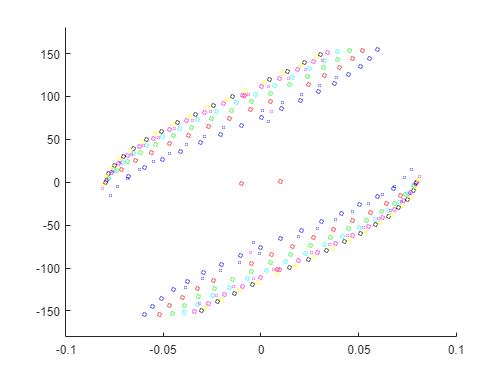


제약 조건을 충족하는 국소 최솟값을 찾았습니다.

목적 함수가 최적성 허용오차의 값 이내에서 실현 가능한 방향에서 감소하지 않고 
제약 조건이 제약 조건 허용오차의 값 이내에서 충족되기 때문에 
최적화가 완료되었습니다.

<중지 기준 세부 정보>

국소 최솟값이 있을 수 있습니다. 제약 조건이 충족되었습니다.

현재 스텝의 크기가 스텝 크기 허용오차 값보다 작고 
제약 조건이 

    for  thetaB2= 10:10:160
            fun = @(x) x(1)^2+x(2)^2;
            A = [];
            b = [];
            Aeq = [];
            beq = [];
            lb = [];
            ub = [];
            c = @(x) abs(abs(x(1))-abs(x(2)))-pi;
            EA0=[0 0];
            ceq=@(x) [E*I*x(1)/-((H*M*v11*mu0*sin((thetaB2*pi/180)-x(1)))-(H*M*v2*mu0*sin((thetaB2*pi/180)-x(2))))-L1;...
            (E*I*(x(2)-x(1))/(H*M*v2*mu0*sin((thetaB2*pi/180)-x(2))))-L+L1];
            nonlinfcn = @(x)deal(c(x),ceq(x));
            x = fmincon(fun,EA0,A,b,Aeq,beq,lb,ub,nonlinfcn);
            A1lin=linspace(0,x(1),500);
            A2lin=linspace(x(1),x(2),500);
            x1=E*I*sin(A1lin)/(-(H*M*v11*mu0*sin((thetaB2*pi/180)-x(1)))+(H*M*v2*mu0*sin((thetaB2*pi/180)-x(2))));
        y1=E*I*(1-cos(A1lin))/(-(H*M*v11*mu0*sin((thetaB2*pi/180)-x(1)))+(H*M*v2*mu0*sin((thetaB2*pi/180)-x(2))));
    
        x10=E*I*sin(x(1))/(-(H*M*v11*mu0*sin((thetaB2*pi/180)-x(1)))+(H*M*v2*mu0*sin((thetaB2*pi/180)-x(2))));
        y10=E*I*(1-cos(x(1)))/(-(H*M*v11*mu0*sin((thetaB2*pi/180)-x(1)))+(H*M*v2*mu0*sin((thetaB2*pi/180)-x(2))));
    
        x2=(E*I*(sin(A2lin)-sin(x(1)))/(H*M*v2*mu0*sin((thetaB2*pi/180)-x(2))))+x10;
        y2=(E*I*(cos(x(1))-cos(A2lin))/(H*M*v2*mu0*sin((thetaB2*pi/180)-x(2))))+y10;
    
    
        xtotal=[x1,x2];
        ytotal=[y1,y2];
        %plot(xtotal,-ytotal)
        %plot(xtotal,ytotal)
        x*180/pi;


         r=(E*I*(cos(x(1))-cos(x(2)))/(H*M*v2*mu0*sin((thetaB2*pi/180)-x(2))))+y10+(0.01*sin(x(1)));
         if r<0
            x(2)=-x(2);
            r=-r;
        end
            plot(r,x(2)*180/pi,'bs','MarkerSize',3)
            plot(-r,-x(2)*180/pi,'bs','MarkerSize',3)
   
    end    